% Package orientation: Runnable validation or benchmark wrapper. It loads saved models or constructs small checks, then reports metrics/diagnostics without changing training code.
% CHECK_GPU_vs_CPU_regression_small.mlx
% Rigorous small-example GPU-vs-CPU primary-decoder equivalence checks.
% The test intentionally stays small so the CPU reference can run in a reasonable time.
clear; clc;
repo_root = project_root();
add_project_paths(repo_root);
%% ---------------- Check Hyperparameters ----------------
% check_seeds runs independent deterministic networks. More seeds increase coverage.
% check_tolerance controls the interpretation threshold for max absolute and relative differences.
% N_hidden and N_rec are deliberately small here; increase them only if CPU runtime is acceptable.
% epochs is the number of bias-training epochs run before the post-training comparison.
check_seeds = [11 42 99];
training_epochs = 100; % Edit this to choose how many CPU/GPU training epochs the check runs.
opts_template = struct();
opts_template.check_tolerance = struct('abs', 5e-4, 'rel', 5e-4);
opts_template.epochs = training_epochs;
opts_template.N_hidden = 64;
opts_template.N_rec = 10;
opts_template.batch_size = 4;
%% ---------------- Time Window ----------------
% Short windows make the check fast while still exercising recurrent dynamics,
% synaptic filtering, output averaging, and the requested optimiser epochs.
opts_template.dt = single(1e-3);
opts_template.PRESENT = struct('T', single(0.3), 'avg_frac', single(0.5));
opts_template.steps_present = max(1, round(opts_template.PRESENT.T / opts_template.dt));
opts_template.steps_avg = max(1, round(opts_template.PRESENT.avg_frac * opts_template.steps_present));
opts_template.k_avg_start = opts_template.steps_present - opts_template.steps_avg + 1;
%% ---------------- Network, Neuron, and Optimiser Parameters ----------------
% These mirror the train scripts but are small enough for CPU verification.
opts_template.SCALE = struct('enc', single(2), 'rec', single(0.05), 'dec', single(0.1));
opts_template.NET = struct('p_rec', 1, 'variance_correction', true, ...
    'dale', struct('enable', true, 'p_exc', 0.5, 'sign', []));
opts_template.neuron = struct('tau_u', single(50e-3), 'tau_w', single(500e-3), ...
    'tau_s_rise', single(2e-3), 'tau_s_decay', single(50e-3), ...
    'E_L', single(-70), 'V_th', single(-50), 'V_reset', single(-65), ...
    'a_param', single(0), 'b_param', single(0.5), ...
    'phi_u', single(1), 'delta_u', single(0.8));
opts_template.SCHED = struct('type', 'exponential', 'lr_start', single(1e-1), 'lr_end', single(5e-3));
opts_template.adam = struct('b1', single(0.9), 'b2', single(0.999), 'eps', single(1e-8));
%% ---------------- Run Multiple Independent Checks ----------------
% Each check compares initial outputs, outputs after opts_template.epochs bias-training epochs, and trained biases.
% This directly tests regression outputs and bias updates between CPU and GPU implementations.
check_results = cell(numel(check_seeds), 1);
for ii = 1:numel(check_seeds)
    opts = opts_template;
    opts.seed = check_seeds(ii);
    check_results{ii} = snn_primary_api('check_static', 'regression', 'cpu', opts);
    check_results{ii}.seed = check_seeds(ii);
end
%% ---------------- Easy Interpretation ----------------
% Start here. verdict says whether each seed is OK, needs scale/context checking, or needs review.
% main_cpu_gpu_abs is the post-training output mismatch. bias_abs is the trained-bias mismatch.
% loss/metric columns compare CPU and GPU performance after training.

% *_diff_vs_training_percent columns compare mismatch size with the amount changed by training.
% Training-effect columns are not errors; they should usually be nonzero because the model learned.
summary = snn_check_summary_table(check_results);
qualitative_columns = {'seed','verdict','output_quality','performance_quality','learning_quality','neural_quality','read_first'};
quantitative_columns = {'seed', ...
    'initial_abs','initial_rms','initial_rel', ...
    'after_abs','after_rms','after_rel', ...
    'bias_before_abs','bias_before_rms','bias_before_rel', ...
    'bias_abs','bias_rms','bias_rel', ...
    'cpu_output_change_abs','gpu_output_change_abs','output_training_effect_abs_diff', ...
    'cpu_bias_change_abs','gpu_bias_change_abs','bias_training_effect_abs_diff', ...

    seed    epochs    output_compared    initial_abs    initial_rel    after_abs     after_rel     bias_abs     bias_rel     loss_after_abs    loss_train_abs    cpu_output_change_abs    gpu_output_change_abs    cpu_bias_change_abs    gpu_bias_change_abs    cpu_initial_loss    gpu_initial_loss    cpu_after_loss    gpu_after_loss    cpu_loss_delta    gpu_loss_delta    cpu_initial_metric    gpu_initial_metric    cpu_after_metric    gpu_after_metric    metric_after_abs    metric_train_abs    cpu_metric_delta    gpu

    'loss_after_abs','loss_after_diff_percent', ...

Worst initial output abs diff:      4.62532e-05


    'metric_after_abs','metric_after_diff_percent', ...

Worst post-training output abs diff: 0.00319922


    'main_diff_vs_training_percent','bias_diff_vs_training_percent','worst_neural_abs'};

Worst post-training bias abs diff:   0.0371799


disp('Qualitative summary:');

Worst post-training loss abs diff:   0.00100109


disp(summary(:, qualitative_columns));

Largest CPU output change from training: 1.14421


disp('Quantitative output and performance comparisons:');

Largest GPU output change from training: 1.14418


disp(summary(:, quantitative_columns));

Largest CPU bias change from training:   3.00518


snn_print_check_interpretation(summary, 'Regression GPU/CPU check');

Largest GPU bias change from training:   3.00478


%% ---------------- Output and Bias Plots ----------------
% These figures show CPU and GPU outputs/biases before training, after training, and CPU-GPU differences.
snn_plot_check_outputs_and_biases(check_results);

Worst post-training metric abs diff: 0.00149876


%% ---------------- Detailed Diagnostic Plots ----------------

Worst neural spike raster abs diff:  1


% First read the verdict panel, then inspect any seed marked REVIEW or CHECK SCALE.

Worst neural rate abs diff [Hz]:    0


snn_plot_check_summary(summary);

Worst neural voltage abs diff:      14.9998


Output arrays compared in 3/3 checks.


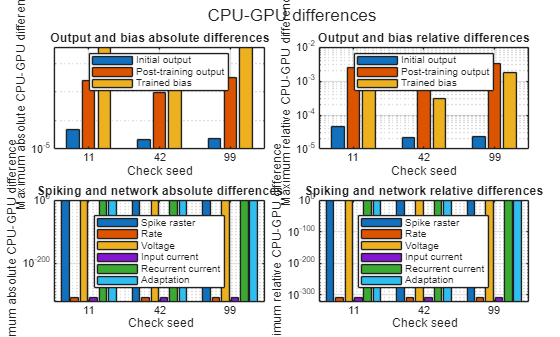

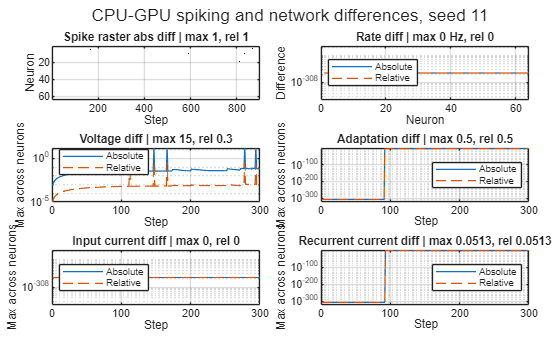

[CHECK neural] seed 11: Static GPU MEX does not expose resident spike rasters; both final models are replayed with the CPU diagnostic recorder for neural comparison.


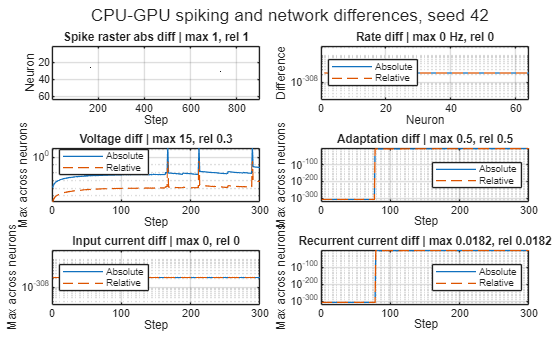

[CHECK neural] seed 42: Static GPU MEX does not expose resident spike rasters; both final models are replayed with the CPU diagnostic recorder for neural comparison.


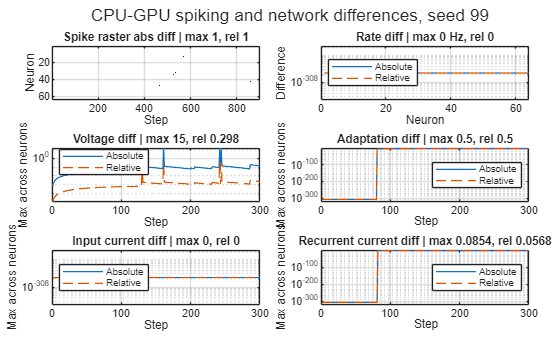

[CHECK neural] seed 99: Static GPU MEX does not expose resident spike rasters; both final models are replayed with the CPU diagnostic recorder for neural comparison.


snn_plot_check_neural_comparison(check_results);